# Logistic Regression for Titanic data classification 

## Load the Titanic data and show it


Train= readtable('train.csv');
Test = readtable('test.csv');
head(Train)

ans = 8×12 table
    PassengerId    Survived    Pclass                             Name                                 Sex        Age    SibSp    Parch      Ticket       Fare       Cabin       Embarked
    ___________    ________    ______    _______________________________________________________    __________    ___    _____    _____    __________    ______    __________    ________

         1            0          3       {'Braund, Mr. Owen Harris'                            }    {'male'  }     22      1        0             NaN      7.25    {0×0 char}     {'S'}  
         2            1          1       {'Cumings, Mrs. John Bradley (Florence Briggs Thayer)'}    {'female'}     38      1        0             NaN    71.283    {'C85'   }     {'C'}  
         3            1          3       {'Heikkinen, Miss. Laina'                             }    {'female'}     26      0        0             NaN     7.925    {0×0 char}     {'S'}  
         4            1          1       {'Futrelle,

head(Test)

ans = 8×11 table
    PassengerId    Pclass                          Name                             Sex        Age     SibSp    Parch      Ticket       Fare       Cabin       Embarked
    ___________    ______    ________________________________________________    __________    ____    _____    _____    __________    ______    __________    ________

        892          3       {'Kelly, Mr. James'                            }    {'male'  }    34.5      0        0      3.3091e+05    7.8292    {0×0 char}     {'Q'}  
        893          3       {'Wilkes, Mrs. James (Ellen Needs)'            }    {'female'}      47      1        0      3.6327e+05         7    {0×0 char}     {'S'}  
        894          2       {'Myles, Mr. Thomas Francis'                   }    {'male'  }      62      0        0      2.4028e+05    9.6875    {0×0 char}     {'Q'}  
        895          3       {'Wirz, Mr. Albert'                            }    {'male'  }      27      0        0      3.1515e+05    8.6625 

## Make the prediction by "sex"


disp(grpstats(Train(:,{'Survived','Sex'}), 'Sex'))

                 Sex        GroupCount    mean_Survived
              __________    __________    _____________

    male      {'male'  }       577           0.18891   
    female    {'female'}       314           0.74204   



gendermdl = grpstats(Train(:,{'Survived','Sex'}), {'Survived','Sex'});
all_female = (gendermdl.GroupCount('0_male') + gendermdl.GroupCount('1_female'))/(577+314);
disp(all_female)

    0.7868



## Preprocess the NaN values

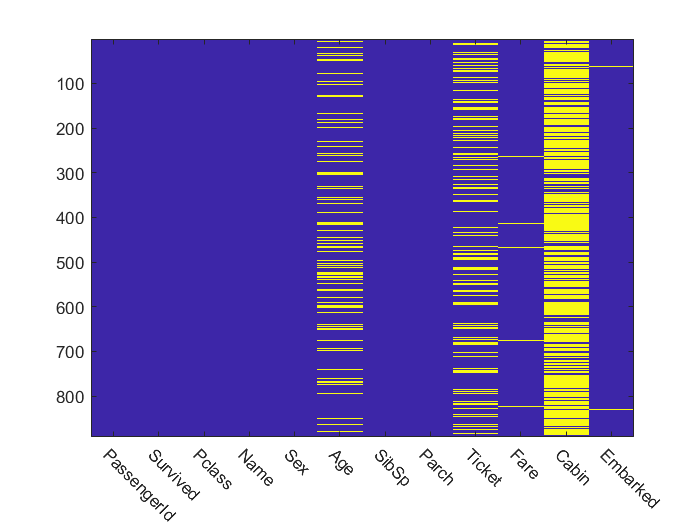

Train.Fare(Train.Fare == 0) = NaN;      % treat 0 fare as NaN
Train.Fare(Train.Fare == 0) = NaN;        % treat 0 fare as NaN
vars = Train.Properties.VariableNames;  % extract column names
figure
imagesc(ismissing(Train))
set(gca,'XTick', 1:12,'XTickLabel',vars);
xtickangle(-45)

% Using the average age replace NaN age
avgAge = nanmean(Train.Age)             % get average age

avgAge = 29.6991

Train.Age(isnan(Train.Age)) = avgAge;   % replace NaN with the average
Test.Age(isnan(Test.Age)) = avgAge; 


% Replace the NaN Fare with the average fare of the correspoinding Pclass
fare = grpstats(Train(:,{'Pclass','Fare'}),'Pclass');   % get class average
disp(fare)

         Pclass    GroupCount    mean_Fare
         ______    __________    _________

    1      1          216         86.149  
    2      2          184         21.359  
    3      3          491         13.788  



for i = 1:height(fare) % for each |Pclass|
    % apply the Pclass average to missing values
    Train.Fare(Train.Pclass == i & isnan(Train.Fare)) = fare.mean_Fare(i);
    Test.Fare(Test.Pclass == i & isnan(Test.Fare)) = fare.mean_Fare(i);
end

% Multi Cabins，No Cabin etc.

train_cabins = cellfun(@strsplit, Train.Cabin, 'UniformOutput', false);
test_cabins = cellfun(@strsplit, Test.Cabin, 'UniformOutput', false);
 
% count the number of tokens
Train.nCabins = cellfun(@length, train_cabins);
Test.nCabins = cellfun(@length, test_cabins);
 
% deal with exceptions - only the first class people had multiple cabins
Train.nCabins(Train.Pclass ~= 1 & Train.nCabins > 1,:) = 1;
Test.nCabins(Test.Pclass ~= 1 & Test.nCabins > 1,:) = 1;
 
% if |Cabin| is empty, then |nCabins| should be 0
Train.nCabins(cellfun(@isempty, Train.Cabin)) = 0;
Test.nCabins(cellfun(@isempty, Test.Cabin)) = 0;

% Embarked is not available
% get most frequent value
disp(grpstats(Train(:,{'Survived','Embarked'}), 'Embarked'))

         Embarked    GroupCount    mean_Survived
         ________    __________    _____________

    S     {'S'}         644           0.33696   
    C     {'C'}         168           0.55357   
    Q     {'Q'}          77           0.38961   



 
% apply it to missling value
for i = 1 : 891
    if isempty(Train.Embarked{i})
        Train.Embarked{i}='S';
    end
end
 
for i = 1 : 418
    if isempty(Test.Embarked{i})
        Test.Embarked{i}='S';
    end
end
 
% convert the data type from categorical to double
Train.Embarked = double(cell2mat(Train.Embarked));
Test.Embarked = double(cell2mat(Test.Embarked));

% change Sex to tpye "double"
for i = 1 : 891
    if strcmp(Train.Sex{i} ,'male')
        Train.Sex{i}=1;
    else
        Train.Sex{i}=0;
    end
end
 
for i = 1 : 418
    if strcmp(Test.Sex{i} ,'male')
        Test.Sex{i}=1;
    else
        Test.Sex{i}=0;
    end
end
Train.Sex = cell2mat(Train.Sex);
Test.Sex = cell2mat(Test.Sex);

% Del some columns
Train(:,{'Name','Ticket','Cabin'}) = [];
Test(:,{'Name','Ticket','Cabin'}) = [];


## Visulization

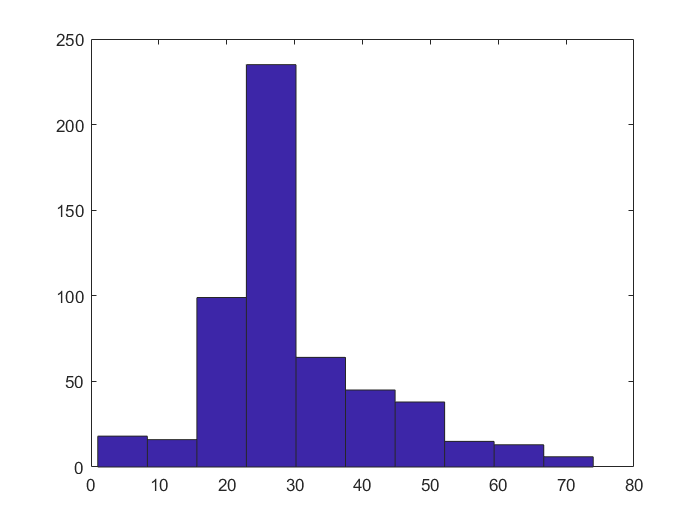


% Age - survived
figure
hist (Train.Age(Train.Survived == 0))   % age histogram of non-survivers

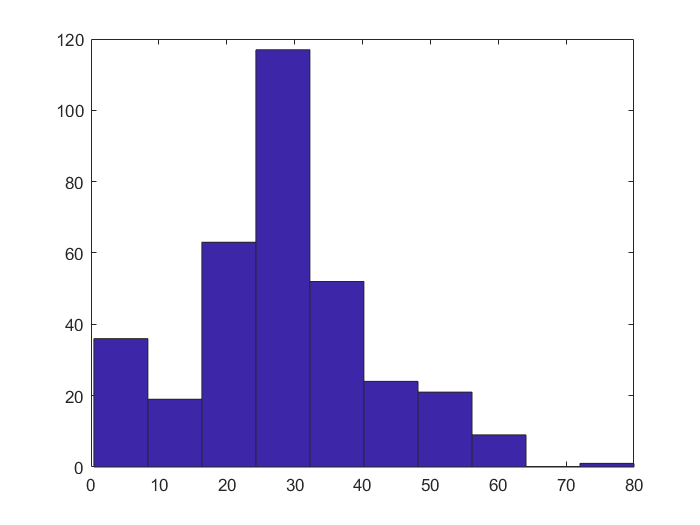

figure
hist (Train.Age(Train.Survived == 1))   % age histogram of survi


A1=sum(Train.Sex(Train.Survived == 1)==0);%存活的男性数量
A2=sum(Train.Sex(Train.Survived == 1)==1);%存活的女性数量
a1=sum(Train.Sex(Train.Survived == 0)==0);%死亡的男性数量
a2=sum(Train.Sex(Train.Survived == 0)==0);%死亡的女性数量
B1=sum(Train.Embarked(Train.Survived == 1)==81);%登船口为Q存活的数量
B2=sum(Train.Embarked(Train.Survived == 1)==83);%登船口为S存活的数量
B3=sum(Train.Embarked(Train.Survived == 1)==67);%登船口为C存活的数量
b1=sum(Train.Embarked(Train.Survived == 0)==81);%登船口为Q死亡的数量
b2=sum(Train.Embarked(Train.Survived == 0)==83);%登船口为S死亡的数量
b3=sum(Train.Embarked(Train.Survived == 0)==67);%登船口为C死亡的数量
P=sum(Train.Survived==1)/(sum(Train.Survived==0)+sum(Train.Survived==1));%存活的概率
Q=sum(Train.Survived==0)/(sum(Train.Survived==0)+sum(Train.Survived==1));%死亡的概率
P1=A1/(A2+A1); %存活的人中男性的概率
P2=1-P1;       %存活的人中女性的概率
P3=a1/(a1+a2);%死亡的人中男性的概率
P4=1-P3;       %死亡的人中女性的概率
Q1 =B1/(B1+B2+B3); %存活的人中登船口为Q的概率
Q2 =B1/(B1+B2+B3);  %存活的人中登船口为S的概率
Q3 =B1/(B1+B2+B3);  %存活的人中登船口为C的概率
q1 =b1/(b1+b2+b3);  %死亡的人中登船口为Q的概率
q2 =b2/(b1+b2+b3);  %死亡的人中登船口为S的概率
q3 =b3/(b1+b2+b3);  %死亡的人中登船口为C的概率
for i=1:418
    data=Test.Variables;
    if data(i,3)==0 && data(i,9)==81
        pa=P*P1*Q1;
        pb=Q*P3*q1;
    end
    if data(i,3)==1 && data(i,9)==81
        pa=P*P2*Q1;
        pb=Q*P4*q1;
        
    end
    if data(i,3)==0 && data(i,9)==83
        pa=P*P1*Q2;
        pb=Q*P3*q2;
        
    end
    if data(i,3)==1 && data(i,9)==83
        pa=P*P2*Q2;
        pb=Q*P4*q2;
        
    end
    if data(i,3)==0 && data(i,9)==67
        pa=P*P1*Q3;
        pb=Q*P3*q3;
        
    end
    if data(i,3)==1 && data(i,9)==67
        pa=P*P2*Q3;
        pb=Q*P4*q3;
    end
    if (pa>pb)
        survived(i,1)=1;
    else
        survived(i,1)=0;
    end
end
PassengerId=Test.PassengerId;
Survived=survived;
R_table=table(PassengerId,Survived);
writetable(R_table,['D:/QQ.csv'])










